Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), 9600, Timeout=5);
configureTerminator(STM32_ser,"CR")
STM32_ser.flush;

STM32_ser.write('e','char');
vettore=read(STM32_ser,100,'uint16');
length(vettore)

ans = 100

display(vettore)

vettore =            0         757        1392        1920        2354        2706        2986        3205        3369        3487        3565        3608        3622        3612        3580        3530        3466        3391        3306        3213        3115        3012        2906        2799        2691        2582        2475        2368        2263        2160        2059        1961        1866        1774        1686        1600        1518        1439        1363        1290        1220        1154        1091        1031         974         920         868         818         771         726


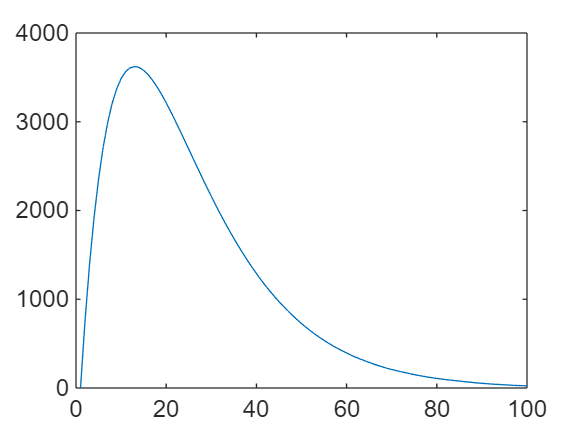

plot(vettore)